## Load Data, Preprocess, Hold Out

%Load Data
dataset = loaddataset();

%Extract Features & Samples
T = table2array(dataset(:,end));
X = normalize(table2array(dataset(:, 2:end-1)), 1); % exclude ID and class; normalize features
%Seperate Training & Hold Out Samples
Icross = crossvalind('kfold',size(X,1),10);
Xholdout = X(Icross == 1, :);
Tholdout = T(Icross == 1);
X = X(Icross ~= 1, :);
T = T(Icross ~= 1);
save('variablesforfitness','X',"T")

## Initial Neural Network Parameters

%% Initialize
maxhidden = round(size(X,2)/10);
repeats = 10;
tmp = zeros(repeats, 2);
summary = zeros(maxhidden, 2);

%% Run & Summary Statistics
for h = 1:maxhidden
	for r = 1:repeats
		[tmp(r, 1), tmp(r, 2)] = neuralnetwork(X, T, h);
	end
	summary(h,:) = [mean(tmp(:,1)), mean(tmp(:,2))];
end

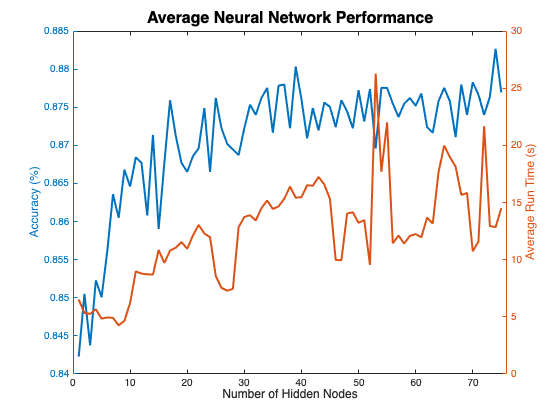


%% Plot
figure
yyaxis left
plot(1:maxhidden, summary(:,1), LineWidth=2)
ylabel('Accuracy (%)', FontSize=12)
xlabel('Number of Hidden Nodes', FontSize=12)
xlim([0 maxhidden+1])
title('Average Neural Network Performance', FontSize=16)
yyaxis right
plot(1:maxhidden, summary(:,2), LineWidth=2)
ylabel('Average Run Time (s)', FontSize=12)

%% Find Optimal Number of Hidden Nodes
%Smooth accuracy, kernel size 3
smoothed = movmean(summary(:,1), 3);
%find smallest node size where accuracy is ≥99% of max
threshold = max(smoothed) * 0.99;
tmp = find(smoothed > threshold);
numhidden = tmp(1)

numhidden = 17

## PCA

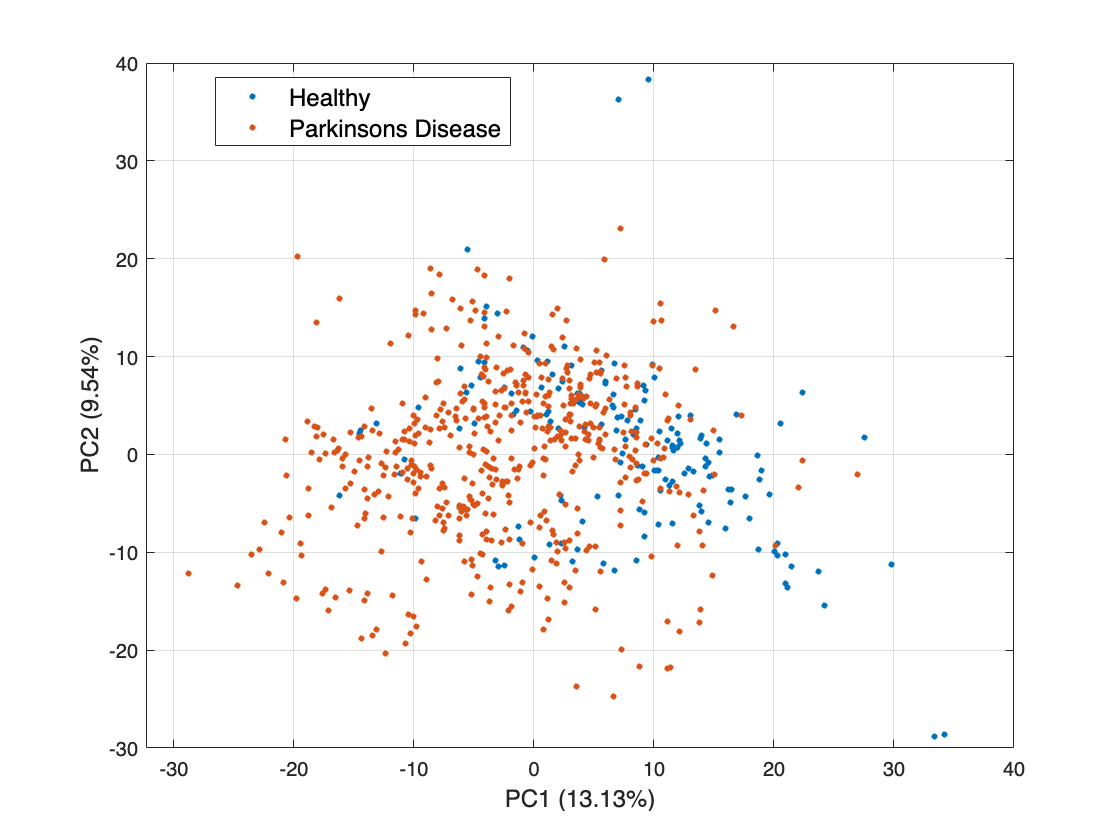

%% Perform PCA
[Evec, Y, Eval] = pca(X);

%% Plot PCA1 x PCA2
figure
gscatter(Y(:,1),Y(:,2), T)
legend('Healthy', 'Parkinsons Disease', FontSize=12);
xlabel(sprintf('PC1 (%.2f%%)', Eval(1)/sum(Eval)*100), FontSize=12);
ylabel(sprintf('PC2 (%.2f%%)', Eval(2)/sum(Eval)*100), FontSize=12);
grid on

%% Performance
%initialize
tmp = zeros(1, repeats);
performance = zeros(size(Y,2), 2); %col 1: reconstruction error, col 2: network accuracy, col 3: run time
EvecT = Evec';
Xc = X - repmat(mean(X,2), 1, size(X, 2));
for i = 1:size(Y,2)
	%Reconstruction Error
	Xrec = Y(:, 1:i) * EvecT(1:i, :);
	performance(i, 1) = sqrt(mean(sum((Xc - Xrec).^2,2)));

	%Accuracy
	for r = 1:repeats; tmp(r) = neuralnetwork(Y, T, numhidden, [true(1, i), false(1, size(Y, 2)-i)]); end
	performance(i, 2) = mean(tmp);
end

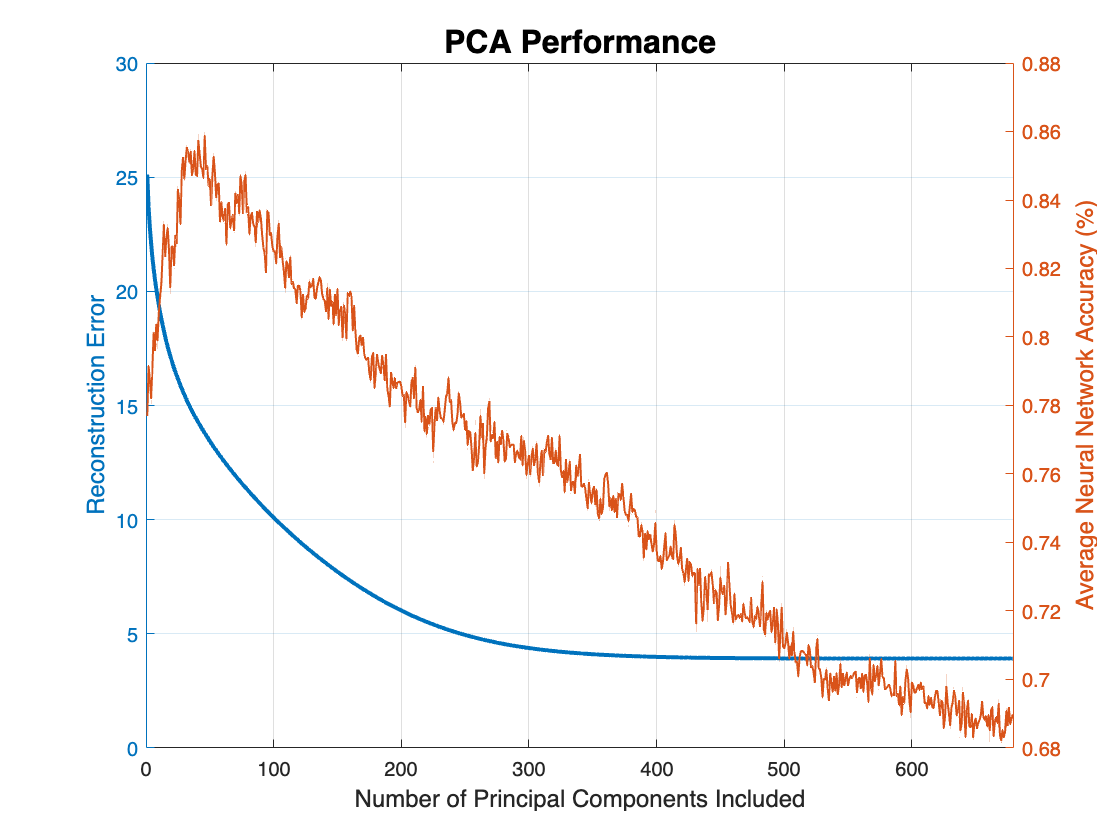


%% Plot Performance
figure()
yyaxis left
plot(1:size(Y,2), performance(:, 1), LineWidth=2)
ylabel('Reconstruction Error', FontSize=12)
xlabel('Number of Principal Components Included', FontSize=12)
xlim([0 size(Y,2)+1])
title('PCA Performance', FontSize=16)
yyaxis right
plot(1:size(Y,2), performance(:, 2), LineWidth=1)
ylabel('Average Neural Network Accuracy (%)', FontSize=12)
grid on

%% Find Optimal Number of Principal Components
%Smooth accuracy, kernel size 3
smoothed = movmean(performance(:,2), 3);
%find smallest node size where accuracy is ≥99% of max
threshold = max(smoothed) * 0.99;
tmp = find(smoothed > threshold);
components = tmp(1)

components = 29

%{
[attributes,sampleclasses,PC,Y,V] = performPCA(dataset);    % perform PCA
[~,numattributes] = size(Y);
for i = 1:numattributes
	%this is where we figure out reconstruction error based on how many
	%principal components get used
    [error(i)] = getReconstructionError(dataset,Y,PC,i);
end

error = zeros(1, size(Y,2))
for i = 1:size(Y,2)
	EvecT = Evec';
	Mrec = Y(:, 1:3) * EvecT(1:3, :);
end

% Create a figure that is reconstruction error vs. number of PC included 
figure()
plot([1:numattributes],error)
hold on
grid on
xlabel('# of Principal Components Included')
ylabel('Reconstruction Error')
ylim([0.7E-11 0.9E-11])

for x = 1:20 %first figure out reconstruction curve, then use that reconstruction curve to determine what is the max number of principal components we care about, e.g., if we use 5 PCs that corresponds to 95% reconstruction accuracy which we call "good enough"
	index = [ones(1, x), zeros(1, size(dataset, 2)-(2+x))]
	[accuracy,~] = neuralnetwork(X, T, index, numhidden)
end
%x is really Y from pca
%t is the target, aka parkinsons or healthy, should be unchanged from raw
%data,
%num hidden will be a variable with a fixed value created in the above
%section
%}

## Feature Selection

%% feature selection, then classification
%Data from running this code is stored in the gadata.mat file
idx=1;
for pop= 50:50:200
	for rep = 1:3
		[selectedfeatures,accuarcy,featureidx]=genfeatureselect(X,T,pop);
		selectedfeaturesperpop{rep}=selectedfeatures;
		accuarcyperpop{rep} = accuarcy;
		featureidxperpop{rep} =	featureidx;
	end
	fullselectedfeatures{idx}=selectedfeaturesperpop;
	fullaccuarcy{idx} = accuarcyperpop;
	fullfeatureidx{idx} =	featureidxperpop;
	idx=idx+1;
end


Single objective optimization:
753 Variables
753 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              100         -0.9016         -0.8729        0
ga stopped because the best penalty function value crossed options.FitnessLimit and 
 the constraint violation is less than options.ConstraintTolerance.

Single objective optimization:
753 Variables
753 Integer variables

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              100         -0.8943         

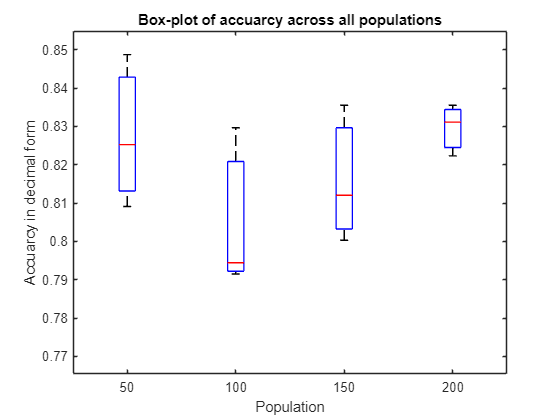

save('gadata.mat','fullfeatureidx','fullaccuarcy','fullselectedfeatures')

%Finding values that correspond to the highest found accuarcy
avgaccuarcy=[];
for iteration =1:length(fullaccuarcy)
	avgaccuarcy(iteration)=mean(cell2mat(fullaccuarcy{iteration}));
end

%Finding highest average and individual accuarcies 
highestavgaccuarcy=max(avgaccuarcy);
highestavgidx=find(avgaccuarcy == highestavgaccuarcy);
highestindvidualacc=max(cell2mat(fullaccuarcy{highestavgidx}));
highestindvidualaccidx=find(highestindvidualacc ==cell2mat(fullaccuarcy{highestavgidx}));

%Displaying data
boxplot(cell2mat(fullaccuarcy{1}),'Positions',1)
hold on
boxplot(cell2mat(fullaccuarcy{2}),'Positions',2)
boxplot(cell2mat(fullaccuarcy{3}),'Positions',3)
boxplot(cell2mat(fullaccuarcy{4}),'Positions',4)
% Setting labels
title('Box-plot of accuarcy across all populations')
xticks([1, 2, 3, 4])
xticklabels({'50', '100','150','200'}); 
xlabel('Population')
ylabel('Accuarcy in decimal form')
hold off

## Method Comparison

%% Initialize
repeats = 25;
summary = zeros(repeats*3, 2);
[~, Yholdout, ~] = pca(Xholdout);

%% Raw data
for r = 1:repeats
	[summary(r, 1), summary(r, 2)] = neuralnetwork(Xholdout, Tholdout, numhidden);
	[summary(r+repeats, 1), summary(r+repeats, 2)] = neuralnetwork(Yholdout, Tholdout, numhidden, [true(1, components), false(1, size(Y, 2)-components)]);
	[summary(r+repeats*2, 1), summary(r+repeats*2, 2)] = neuralnetwork(Xholdout, Tholdout, numhidden,fullfeatureidx{highestavgidx}{highestindvidualaccidx}); %index found in feature selection%);
end

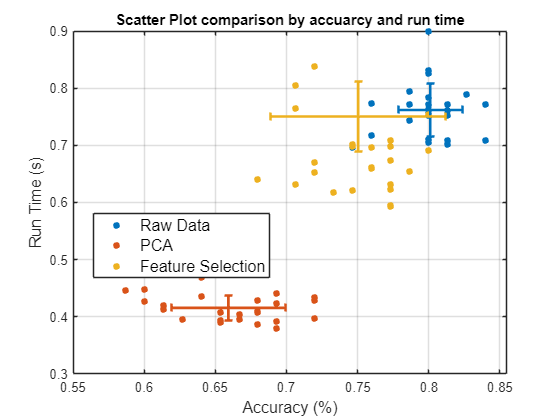

%% Plot
figure()
gscatter(summary(:,1), summary(:,2), [ones(1, repeats), repmat(2, 1, repeats), repmat(3, 1, repeats)])
hold on
errorbar(mean(summary(1:25,1)), mean(summary(1:25,2)), ...
	-std(summary(1:25,2)), std(summary(1:25,2)), -std(summary(1:25,1)), std(summary(1:25,1)), Color = [0 0.4470 0.7410], LineWidth=2)
errorbar(mean(summary(26:50,1)), mean(summary(26:50,2)), ...
	-std(summary(26:50,2)), std(summary(26:50,2)), -std(summary(26:50,1)), std(summary(26:50,1)), Color = [0.8500 0.3250 0.0980], LineWidth=2)
errorbar(mean(summary(51:end,1)), mean(summary(51:end,1)), ...
	-std(summary(51:end,2)), std(summary(51:end,2)), -std(summary(51:end,2)), std(summary(51:end,2)), Color = [0.9290 0.6940 0.1250], LineWidth=2)
%doc gscatter contains color info for other classes
title('Scatter Plot comparison by accuarcy and run time')
xlabel('Accuracy (%)', FontSize=12)
ylabel('Run Time (s)', FontSize=12)
legend('Raw Data', 'PCA', 'Feature Selection', FontSize=12);
grid on
hold off